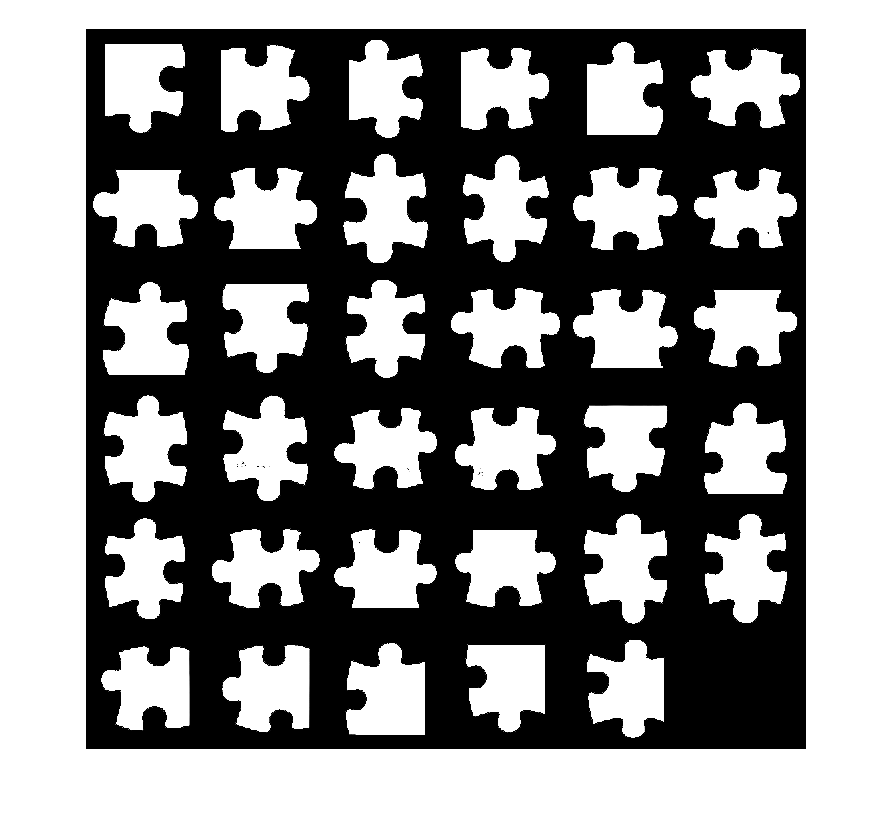

mJigSaw = rgb2gray(imread('puzzle_5_7.jpg'));
mJigsawTemplate = imbinarize(mJigSaw, 'global');
 
mI = rgb2gray(imread('KoalaMitBaby.jpg'));

mMontage = createJigsaw(mI, mJigsawTemplate, false);

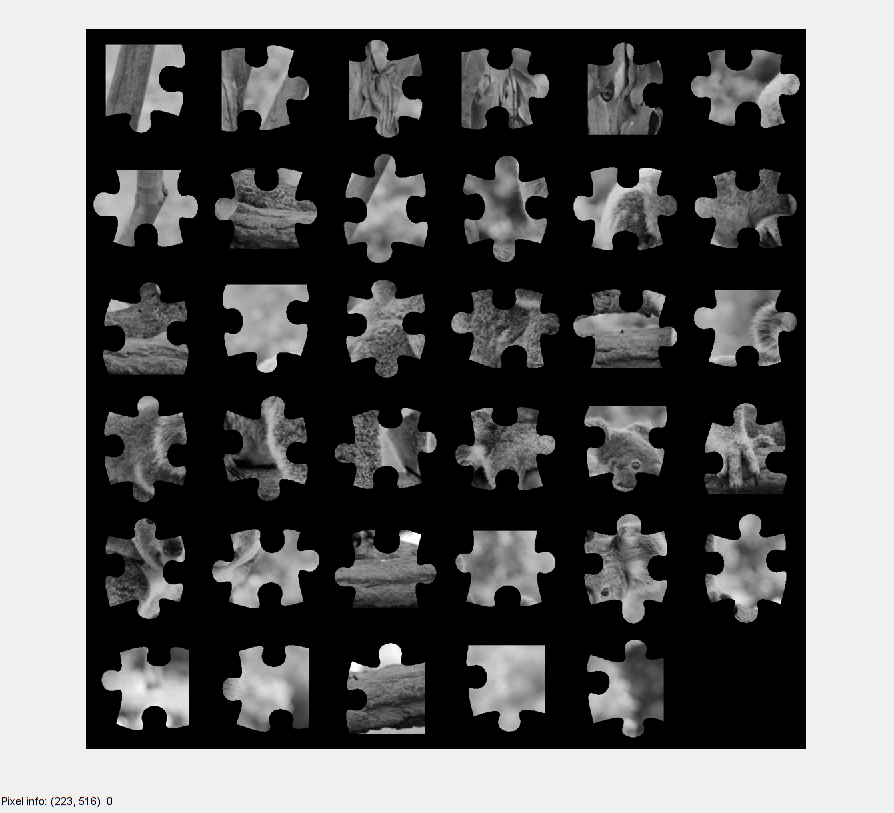

 
imshow(mMontage, []), impixelinfo

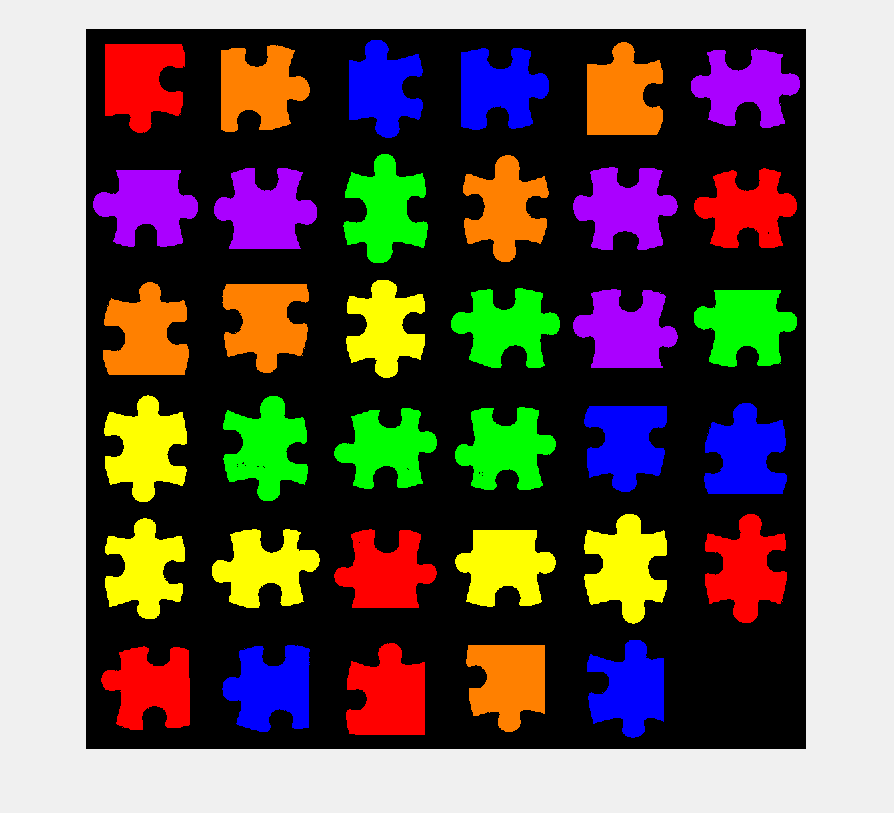


mI_label = bwlabel(mMontage);
mI_labelcolor = label2rgb(mI_label, 'prism', 'k', 'shuffle');
imshow(mI_labelcolor);

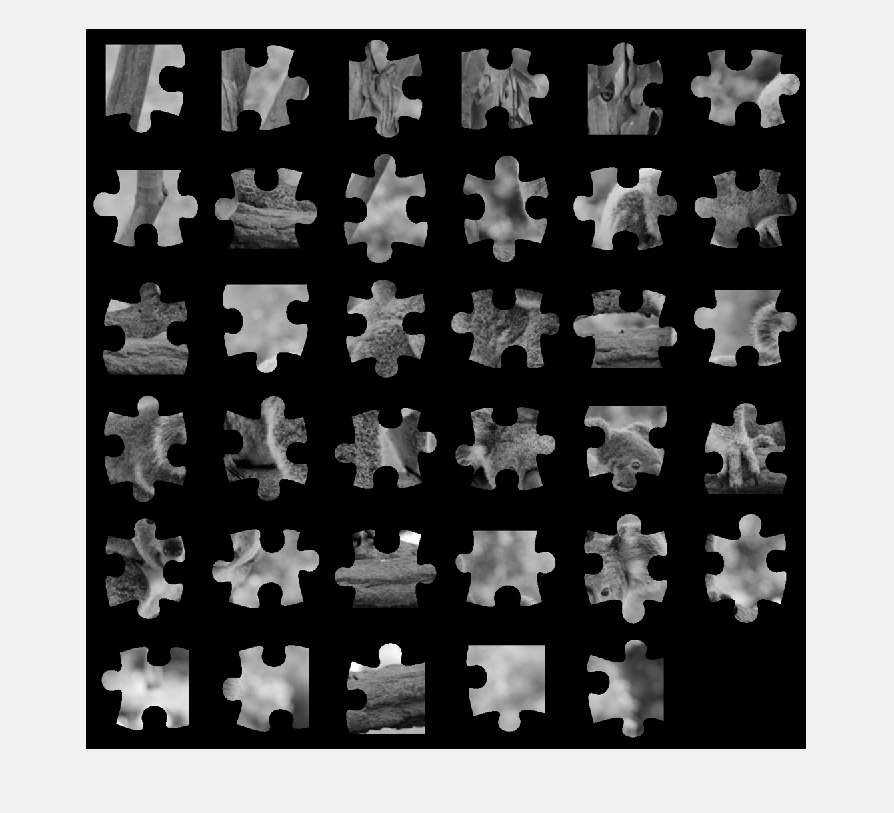

imshow(mMontage);

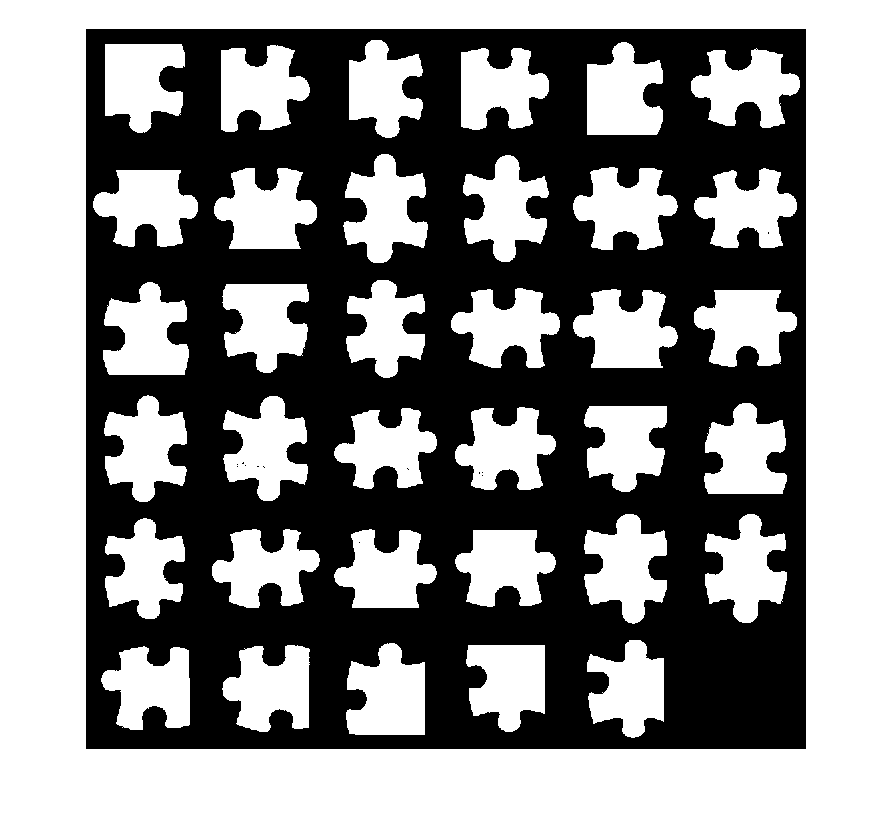

mI_b = imbinarize(mMontage, 0.001);
imshow(mI_b);

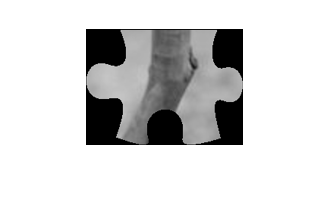

The following error occurred converting from JigsawPiece to double:
Conversion to double from JigsawPiece is not possible.

[B,L] = bwboundaries(mI_b, 8, 'noholes');

mI_pieces = zeros(length(B));

for k = 1:length(B)
   boundary = B{k};
   minPoint = min(boundary);
   maxPoint = max(boundary);
   
   width = maxPoint(2) - minPoint(2);
   height = maxPoint(1) - minPoint(1);
   
   mI_part = imcrop(mMontage, [minPoint(2), minPoint(1), width, height]);   
   
   figure, imshow(mI_part);

   jigsaw_piece = JigsawPiece(mI_part);
   mI_pieces(k) = jigsaw_piece;
end